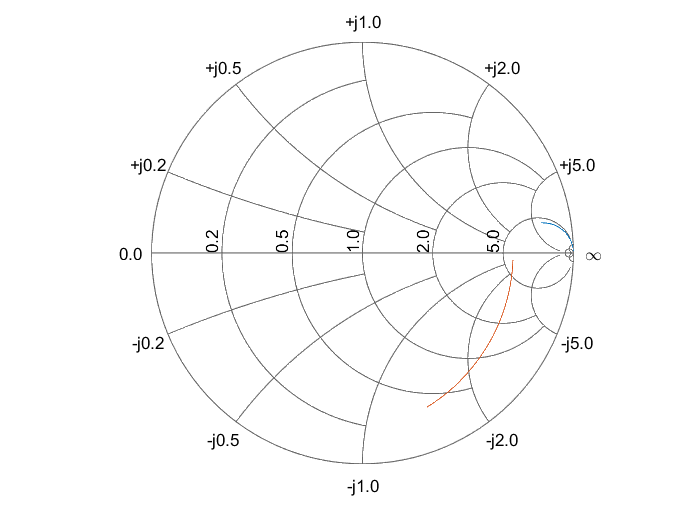

R = 300; L = 2.2e-6; C = 3e-12; Z0 = 50;

f = 75e6:1e6:700e6;
XL = 1i*2*pi.*f*L;
XC = -1i./(2*pi.*f*C);

% Cálculo de impedancias
Zs = R + XL + XC;
Zp = 1./(1/R + 1./XL + 1./XC);

% Conversión y gráficos
G1 = z2gamma (Zs,Z0);
G2 = z2gamma (Zp,Z0);
h1 = smithchart(G1); hold on
h2 = smithchart(G2);
hold off

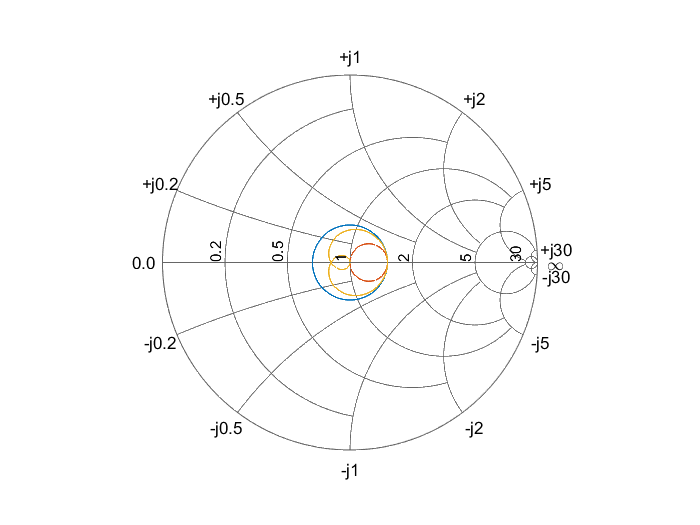

f = 60e6;
Z0 = 50;
ZL = 75;
Z1 = sqrt(Z0*ZL);
f_f0  = 0:1e-3:4;
theta = pi/2*f_f0;

% Impedancia Zin sin adaptar
Zin_0 = Z0*(ZL+1i*Z0*tan(theta)) ./ (Z0+1i*ZL*tan(theta)); GZin_0 = z2gamma(Zin_0);
Zin_1 = Z1*(ZL+1i*Z1*tan(theta)) ./ (Z1+1i*ZL*tan(theta)); GZin_1 = z2gamma(Zin_1); 
Zin_2 = Z0*(Zin_1+1i*Z0*tan(theta)) ./ (Z0+1i*Zin_1.*tan(theta)); GZin_2 = z2gamma(Zin_2); 

figure; % Create a new 
smithplot(GZin_0);
hold on
smithplot(GZin_1);
smithplot(GZin_2);